clc;
clear;
close all;

Fs = 44100;
bits = 16;
channels = 1;

deviceID = 2; % CHANGE THIS

duration = 5;



%record
recObj = audiorecorder(Fs, bits, channels, deviceID);

disp('Speak now...');

Speak now...


recordblocking(recObj, duration);
disp('Done recording');

Done recording



audioData = getaudiodata(recObj);

disp(max(audioData))

    0.0725



disp(min(audioData))

   -0.0811



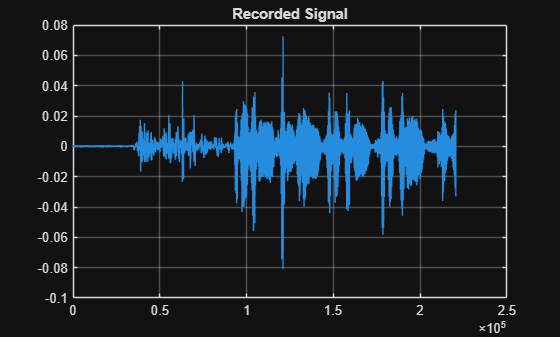


figure;
plot(audioData);
title('Recorded Signal');
grid on;

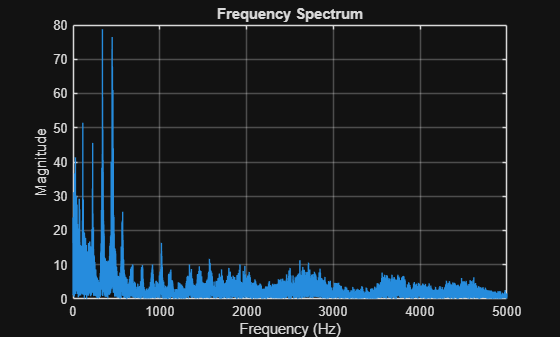


%play sound
soundsc(audioData, Fs);
pause(length(audioData)/Fs + 1);

%analysis
N = length(audioData);

X = fft(audioData);

f = (0:N-1)*(Fs/N);

magnitude = abs(X);

figure;
plot(f, magnitude);

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');

xlim([0 5000]);
grid on;

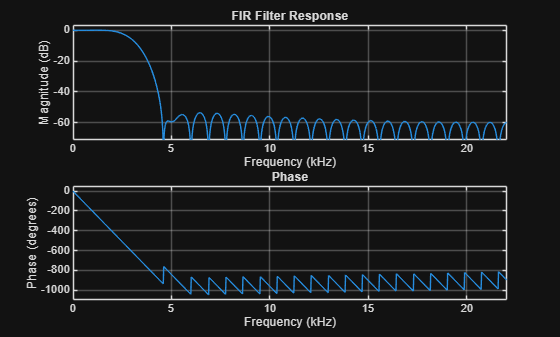


%FIR filter
fc = 3000;      % Cutoff frequency
order = 50;     % Filter order

% Normalize cutoff frequency
Wn = fc / (Fs/2);

% FIR coefficients
window = hamming(order + 1);

b = fir1(order, Wn, 'low', window);

% Frequency response
figure;
freqz(b,1,1024,Fs);
title('FIR Filter Response');

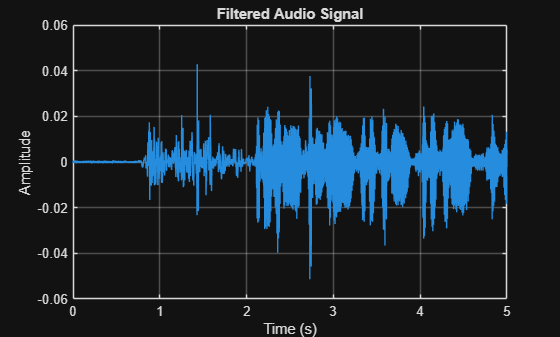


%apply FIR filter

filteredAudio = filter(b, 1, audioData);
t = (0:length(filteredAudio)-1)/Fs;

figure;
plot(t, filteredAudio);

xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Audio Signal');
grid on;

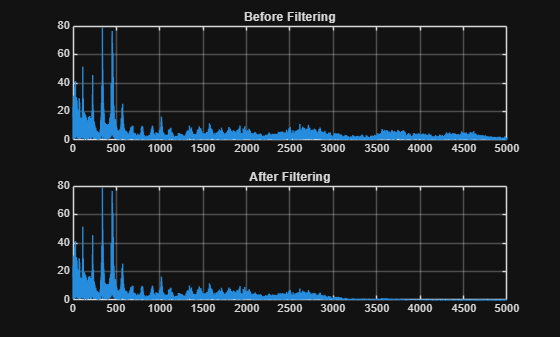


soundsc(filteredAudio, Fs);

%FFT to filtered
Y = fft(filteredAudio);

figure;

subplot(2,1,1);
plot(f, abs(X));
title('Before Filtering');
xlim([0 5000]);
grid on;

subplot(2,1,2);
plot(f, abs(Y));
title('After Filtering');
xlim([0 5000]);
grid on;